# Lab6

# MirHamed Jafarzadeh - 810195374

# Sajjad Pakdaman Savoji - 810195517

## *Part 6 - 1: Initialization of Parameters ("dcl_init.m" Loading)*

clear
close all
clc
dcl_init

## *Part 6 - 2: FSK-Modulation Transmitter Implementation*

**1.  Bit Generating**

b_tx = bit_gen(pkt_size, k)

b_tx =      0     1
     1     0
     0     0
     1     1
     1     0
     1     1
     0     0
     1     0
     0     1
     1     0


**2. Bit-to-Symbol Mapping**

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0     0
     0     1
     1     0
     1     1


sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
sym_idx

sym_idx =      2     3     1     4     3     4     1     3     2     3     4     3     4     4     1     4     1     2     3     4     4     3     4     2     4     3     3     3     3     4     2     1     3     1     4     1     2     1     1     3     4     4     4     4     1     1     1     4     4     2


**3. Transmitting Pulse Shaping**

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv')

tx_smpl =    0.1250 + 0.0000i   0.1248 + 0.0061i   0.1244 + 0.0123i   0.1236 + 0.0183i   0.1226 + 0.0244i   0.1213 + 0.0304i   0.1196 + 0.0363i   0.1177 + 0.0421i   0.1155 + 0.0478i   0.1130 + 0.0534i   0.1102 + 0.0589i   0.1072 + 0.0643i   0.1039 + 0.0694i   0.1004 + 0.0745i   0.0966 + 0.0793i   0.0926 + 0.0839i   0.0884 + 0.0884i   0.0839 + 0.0926i   0.0793 + 0.0966i   0.0745 + 0.1004i   0.0694 + 0.1039i   0.0643 + 0.1072i   0.0589 + 0.1102i   0.0534 + 0.1130i   0.0478 + 0.1155i   0.0421 + 0.1177i   0.0363 + 0.1196i   0.0304 + 0.1213i   0.0244 + 0.1226i   0.0183 + 0.1236i   0.0123 + 0.1244i   0.0061 + 0.1248i   0.0000 + 0.1250i  -0.0061 + 0.1248i  -0.0123 + 0.1244i  -0.0183 + 0.1236i  -0.0244 + 0.1226i  -0.0304 + 0.1213i  -0.0363 + 0.1196i  -0.0421 + 0.1177i  -0.0478 + 0.1155i  -0.0534 + 0.1130i  -0.0589 + 0.1102i  -0.0643 + 0.1072i  -0.0694 + 0.1039i  -0.0745 + 0.1004i  -0.0793 + 0.0966i  -0.0839 + 0.0926i  -0.0884 + 0.0884i  -0.0926 + 0.0839i


## *Part 6 - 3: Channel Modeling*

**1.  Adding Delay to Channel**

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed = [delay tx_smpl];

**2.  Adding Phase Offset to Channel**

rx_smpl = tx_smpl_delayed.*exp(1i * chnl_phase_offset);

**3.  Channel Simulation With White Gaussian Noise**

**        3.1. Compute Noise Characteristics**

Es_avg = 1;
Eb = Es_avg / log2(M);
EbNo = db2pow(10);
var_noise = 0.5*(Eb/EbNo);

**        3.2. Adding Noise to Signal**

n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
noise_smpl = n_real + 1i*n_imag;
rx_smpl_noise = rx_smpl + noise_smpl;

## *Part 6 - 4: Modulation Reciever Implementation*

**1.  Pulse Demodulation**

rx_smpl = rx_smpl_noise(chnl_delay_in_smpl+1:end);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');

**2.  Symbol-to-Bit Conversion**

det_bit = b_gray(det_sym_idx, :);

**3.  SER computation**

ser = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)

ser = 0

**4.  BER computation**

ber = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)

ber = 0

## *Part 6 - 5: General Claims*

**1.  SER and BER Computations and Plots of ****Simulation**** vs ****MATLAB****:**

**    i. 2-FSK**

M = 2;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


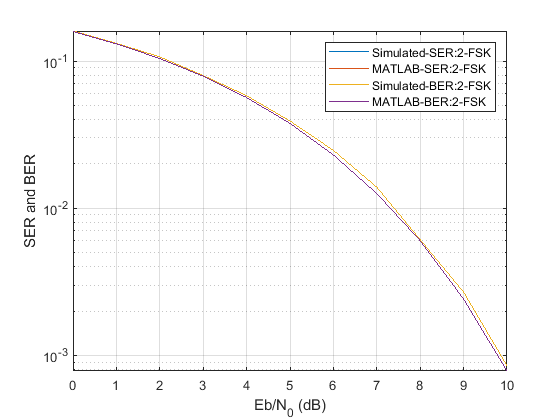

sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_2_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_2_fsk = [delay tx_smpl_2_fsk];
rx_smpl_2_fsk = tx_smpl_delayed_2_fsk.*exp(1i * chnl_phase_offset);

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_2_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_2_fsk./EbNo);

ser_2_fsk = zeros(length(var_noise), 1);
ber_2_fsk = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_2_fsk = rx_smpl_2_fsk + noise_smpl;
    
    rx_smpl_out_2_fsk = rx_smpl_noise_2_fsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_2_fsk, rx_sym_2_fsk] = pulse_demodulation(rx_smpl_out_2_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
     
    det_bit_2_fsk = b_gray(det_sym_idx_2_fsk, :);
    
    ser_2_fsk(i) = 1 - sum(det_sym_idx_2_fsk == sym_idx)/length(sym_idx);
    
    ber_2_fsk(i) = 1 - sum(sum(det_bit_2_fsk == b_tx))/size(det_bit_2_fsk, 1)/size(det_bit_2_fsk, 2);
end

[ber_mat_2_fsk, ser_mat_2_fsk] = berawgn(SNR, 'fsk', M, 'coherent');

semilogy(SNR, [ser_2_fsk ser_mat_2_fsk ber_2_fsk ber_mat_2_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:2-FSK','MATLAB-SER:2-FSK','Simulated-BER:2-FSK','MATLAB-BER:2-FSK')
grid


ber_2_fsk_zero = ber_2_fsk;

**    ii. 4-FSK**

M = 4;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0     0
     0     1
     1     0
     1     1


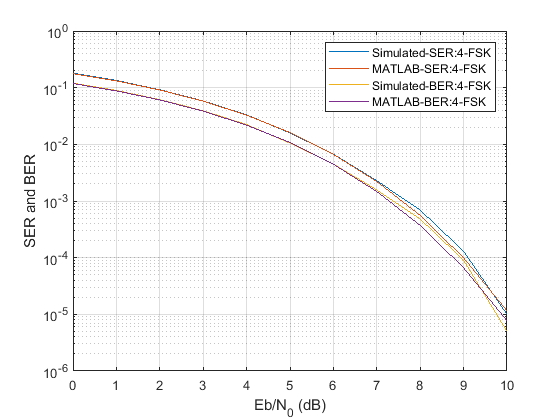

sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_4_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_4_fsk = [delay tx_smpl_4_fsk];
rx_smpl_4_fsk = tx_smpl_delayed_4_fsk.*exp(1i * chnl_phase_offset);

SNR = (snr_min:snr_step:snr_max)';
Eb_4_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_4_fsk./EbNo);

ser_4_fsk = zeros(length(var_noise), 1);
ber_4_fsk = zeros(length(var_noise), 1);
for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_4_fsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_4_fsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_4_fsk = rx_smpl_4_fsk + noise_smpl;
    
    rx_smpl_out_4_fsk = rx_smpl_noise_4_fsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_4_fsk, rx_sym_4_fsk] = pulse_demodulation(rx_smpl_out_4_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
     
    det_bit_4_fsk = b_gray(det_sym_idx_4_fsk, :);
    
    ser_4_fsk(i) = 1 - sum(det_sym_idx_4_fsk == sym_idx)/length(sym_idx);
    
    ber_4_fsk(i) = 1 - sum(sum(det_bit_4_fsk == b_tx))/size(det_bit_4_fsk, 1)/size(det_bit_4_fsk, 2);
end

[ber_mat_4_fsk, ser_mat_4_fsk] = berawgn(SNR, 'fsk', M, 'coherent');

semilogy(SNR, [ser_4_fsk ser_mat_4_fsk ber_4_fsk ber_mat_4_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:4-FSK','MATLAB-SER:4-FSK','Simulated-BER:4-FSK','MATLAB-BER:4-FSK')
grid

**    iii. 8-FSK**

M = 8;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1


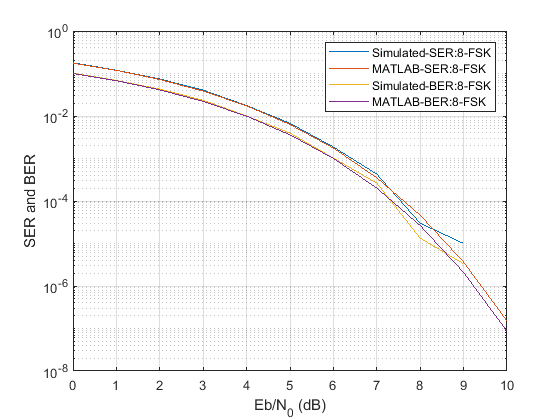

sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_8_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_8_fsk = [delay tx_smpl_8_fsk];
rx_smpl_8_fsk = tx_smpl_delayed_8_fsk.*exp(1i * chnl_phase_offset);

SNR = (snr_min:snr_step:snr_max)';
Eb_8_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_8_fsk./EbNo);

ser_8_fsk = zeros(length(var_noise), 1);
ber_8_fsk = zeros(length(var_noise), 1);
for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_8_fsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_8_fsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_8_fsk = rx_smpl_8_fsk + noise_smpl;
    
    rx_smpl_out_8_fsk = rx_smpl_noise_8_fsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_8_fsk, rx_sym_8_fsk] = pulse_demodulation(rx_smpl_out_8_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
     
    det_bit_8_fsk = b_gray(det_sym_idx_8_fsk, :);
    
    ser_8_fsk(i) = 1 - sum(det_sym_idx_8_fsk == sym_idx)/length(sym_idx);
    
    ber_8_fsk(i) = 1 - sum(sum(det_bit_8_fsk == b_tx))/size(det_bit_8_fsk, 1)/size(det_bit_8_fsk, 2);
end

[ber_mat_8_fsk, ser_mat_8_fsk] = berawgn(SNR, 'fsk', M, 'coherent');

semilogy(SNR, [ser_8_fsk ser_mat_8_fsk ber_8_fsk ber_mat_8_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:8-FSK','MATLAB-SER:8-FSK','Simulated-BER:8-FSK','MATLAB-BER:8-FSK')
grid

**    iv. BER Plot for 2-FSK, 4-FSK and 8-FSK**

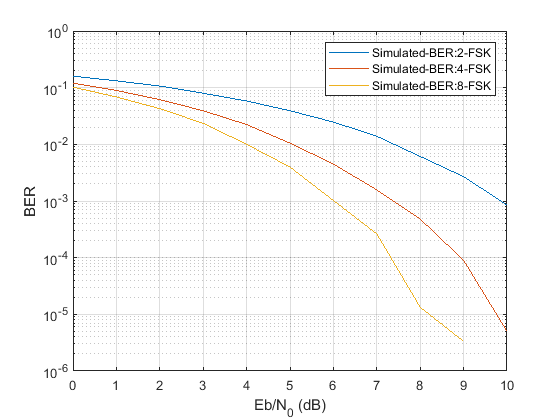

semilogy(SNR, [ber_2_fsk ber_4_fsk ber_8_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('BER')
legend('Simulated-BER:2-FSK','Simulated-BER:4-FSK','Simulated-BER:8-FSK')
grid

**2.  Delay Effect on Channel**

**        2.1 Effect of Delay on BER**

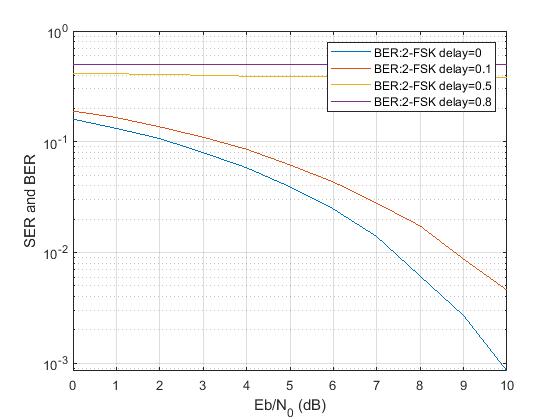

M = 2;
k = log2(M);
delay_coefs = [0.1, 0.5, 0.8];

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb');
else
    b_gray = gray_code(k);
end
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_2_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');

% noise specifications
SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_2_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_2_fsk./EbNo);
ber_2_fsk = zeros(length(var_noise), length(delay_coefs));

for j=1:length(delay_coefs)
    chnl_delay_in_smpl = round(delay_coefs(j)*smpl_per_symbl);
    % make delay
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed_2_fsk = [delay tx_smpl_2_fsk];
    % phase shift (here is zero)
    rx_smpl_2_fsk = tx_smpl_delayed_2_fsk.*exp(1i * chnl_phase_offset);
    
    for i = 1:length(var_noise)
        % add noise
        n_real = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        n_imag = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        noise_smpl = n_real + 1i*n_imag;
        rx_smpl_noise_2_fsk = rx_smpl_2_fsk + noise_smpl;
        % demuodulation
        rx_smpl_out_2_fsk = rx_smpl_noise_2_fsk(1:end-chnl_delay_in_smpl);
        [det_sym_idx_2_fsk, rx_sym_2_fsk] = pulse_demodulation(rx_smpl_out_2_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
        det_bit_2_fsk = b_gray(det_sym_idx_2_fsk, :);
        
        ber_2_fsk(i,j) = 1 - sum(sum(det_bit_2_fsk == b_tx))/size(det_bit_2_fsk, 1)/size(det_bit_2_fsk, 2);
    end
end

semilogy(SNR, [ber_2_fsk_zero ber_2_fsk(:,1) ber_2_fsk(:,2) ber_2_fsk(:,3)])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('BER:2-FSK delay=0', 'BER:2-FSK delay=0.1', 'BER:2-FSK delay=0.5', 'BER:2-FSK delay=0.8')
grid

*It is obvious that delay has a very bad effect on BER*

**        2.2.  Adding Header**

hder_bit = repmat(de2bi(hex2dec('1C6387FF5DA4FA325C895958DC5'))', 1, k);

b_tx = bit_gen(pkt_size, k);
% add header
b_tx = cat(1, hder_bit, b_tx);

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb');
else
    b_gray = gray_code(k);
end
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_2_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');
% pick time samples of header
hder_smpl = tx_smpl_2_fsk(1:size(hder_bit, 1)*smpl_per_symbl);

**        2.3.  Estimation of Packet Beginning and Compensation of Delay Effect**

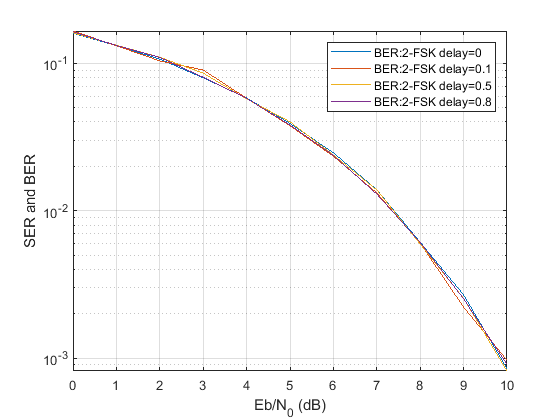

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_2_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_2_fsk./EbNo);
ber_2_fsk = zeros(length(var_noise), length(delay_coefs));

for j=1:length(delay_coefs)
    chnl_delay_in_smpl = round(delay_coefs(j)*smpl_per_symbl);
    % make delay
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed_2_fsk = [delay tx_smpl_2_fsk];
    % phase shift (here is zero)
    rx_smpl_2_fsk = tx_smpl_delayed_2_fsk.*exp(1i * chnl_phase_offset); 
    
    for i = 1:length(var_noise)
        % add noise
        n_real = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        n_imag = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        noise_smpl = n_real + 1i*n_imag;
        rx_smpl_noise_2_fsk = rx_smpl_2_fsk + noise_smpl;
        % demuodulation
        % find start of data
        kernel = conj(fliplr(hder_smpl));
        crr = conv(kernel, rx_smpl_noise_2_fsk);
        [~, idx] = max(real(crr));
        hder_start = idx - length(kernel) + 1;
        if hder_start < 1
            hder_start = 1;
        end
        rx_smpl_out_2_fsk = rx_smpl_noise_2_fsk(hder_start:end);
        % make signals same length (if needed)
        if length(rx_smpl_out_2_fsk) > length(tx_smpl_2_fsk)
            last_index = length(tx_smpl_2_fsk);
            signal = rx_smpl_out_2_fsk(1:last_index);
        elseif length(rx_smpl_out_2_fsk) < length(tx_smpl_2_fsk)
            signal = [rx_smpl_out_2_fsk zeros(1, length(tx_smpl_2_fsk) - length(rx_smpl_out_2_fsk))];
        else
            last_index = length(rx_smpl_out_2_fsk);
            signal = rx_smpl_out_2_fsk(1:last_index);
        end
        
        [det_sym_idx_2_fsk, rx_sym_2_fsk] = pulse_demodulation(signal, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
        
        det_bit_2_fsk = b_gray(det_sym_idx_2_fsk, :);
        
        ber_2_fsk(i,j) = 1 - sum(sum(det_bit_2_fsk == b_tx))/size(det_bit_2_fsk, 1)/size(det_bit_2_fsk, 2);
    end
end

semilogy(SNR, [ber_2_fsk_zero ber_2_fsk(:,1) ber_2_fsk(:,2) ber_2_fsk(:,3)])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('BER:2-FSK delay=0', 'BER:2-FSK delay=0.1', 'BER:2-FSK delay=0.5', 'BER:2-FSK delay=0.8')
grid

*please note that in low SNR values, we may find header start with *$\pm 1\;\mathrm{or}\;2$* error, so we made signals same legnth if needed.*

*It is obvious that we compensated the delay effect on BER, using the header. (for ber which is lower than the actual ber without delay, we must say that the reason is because of different noises we used in these simulations.)*

**3.  Adding Phase to Channel and Phase Estimation**

**        3.1 Effect of Additional Phase on BER**

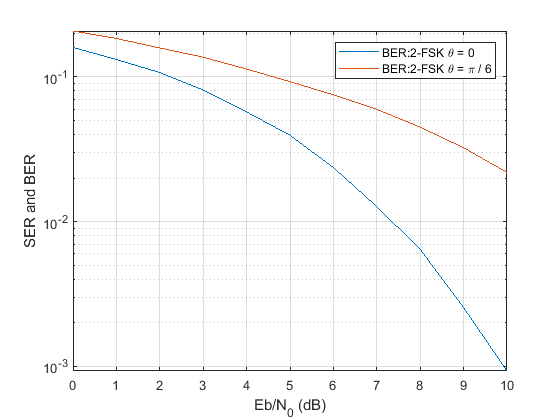

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_2_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_2_fsk./EbNo);
chnl_delay_in_smpl = 0;
phase_coefs = [0, 30];
ber_2_fsk = zeros(length(var_noise), length(phase_coefs));

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb');
else
    b_gray = gray_code(k);
end
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_2_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');

for j=1:length(phase_coefs)
    % change phase shift value
    chnl_phase_offset = phase_coefs(j)*pi/180;
    % make delay (here is zero)
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed_2_fsk = [delay tx_smpl_2_fsk];
    % phase shift
    rx_smpl_2_fsk = tx_smpl_delayed_2_fsk.*exp(1i * chnl_phase_offset); 
    
    for i = 1:length(var_noise)
        % add noise
        n_real = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        n_imag = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        noise_smpl = n_real + 1i*n_imag;
        rx_smpl_noise_2_fsk = rx_smpl_2_fsk + noise_smpl;
        rx_smpl_out_2_fsk = rx_smpl_noise_2_fsk(1:end);
        % demuodulation
        [det_sym_idx_2_fsk, rx_sym_2_fsk] = pulse_demodulation(rx_smpl_out_2_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
         
        det_bit_2_fsk = b_gray(det_sym_idx_2_fsk, :);
        
        ber_2_fsk(i,j) = 1 - sum(sum(det_bit_2_fsk == b_tx))/size(det_bit_2_fsk, 1)/size(det_bit_2_fsk, 2);
    end
end

semilogy(SNR, [ber_2_fsk(:,1) ber_2_fsk(:,2)])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('BER:2-FSK \theta = 0', 'BER:2-FSK \theta = \pi / 6')
grid

*The first ber, is for the case ****without phase offset**** and the second, is for ****30 degrees phase offset****. It is obvious that phase offset has a very bad effect on BER. It is because phase offset has real and imaginary parts, so the signals change in both coordinates.*

**        3.2.  Additional Phase Estimation**

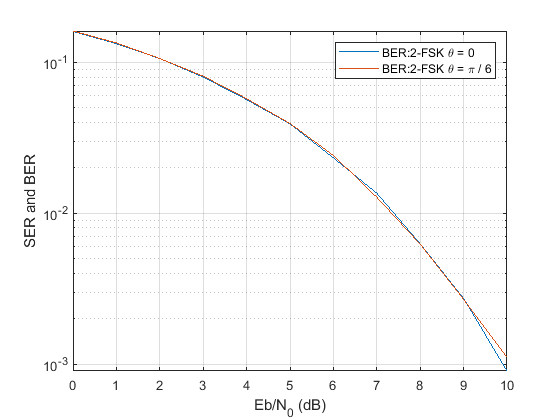

hder_bit = repmat(de2bi(hex2dec('1C6387FF5DA4FA325C895958DC5'))', 1, k);

b_tx = bit_gen(pkt_size, k);
% add header
b_tx = cat(1, hder_bit, b_tx);

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb');
else
    b_gray = gray_code(k);
end
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_2_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv');
% pick time samples of header
hder_smpl = tx_smpl_2_fsk(1:size(hder_bit, 1)*smpl_per_symbl);

ber_2_fsk = zeros(length(var_noise), length(phase_coefs));

for j=1:length(phase_coefs)
    % change phase shift value
    chnl_phase_offset = phase_coefs(j)*pi/180;
    % make delay (here is zero)
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed_2_fsk = [delay tx_smpl_2_fsk];
    % phase shift
    rx_smpl_2_fsk = tx_smpl_delayed_2_fsk.*exp(1i * chnl_phase_offset); 
    
    for i = 1:length(var_noise)
        % add noise
        n_real = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        n_imag = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
        noise_smpl = n_real + 1i*n_imag;
        rx_smpl_noise_2_fsk = rx_smpl_2_fsk + noise_smpl;
        % phase compensation on receiver
        rx_smpl_out_2_fsk = rx_smpl_noise_2_fsk(1:end);
        kernel = conj(fliplr(hder_smpl));
        crr = conv(kernel, rx_smpl_out_2_fsk);
        [~, last_hdr_indx] = max(real(crr));
        ph = angle(crr(last_hdr_indx));
        rx_smpl_out_2_fsk = rx_smpl_out_2_fsk .*exp(-1i * ph);
        % demuodulation
        [det_sym_idx_2_fsk, rx_sym_2_fsk] = pulse_demodulation(rx_smpl_out_2_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator');
         
        det_bit_2_fsk = b_gray(det_sym_idx_2_fsk, :);
        
        ber_2_fsk(i,j) = 1 - sum(sum(det_bit_2_fsk == b_tx))/size(det_bit_2_fsk, 1)/size(det_bit_2_fsk, 2);
    end
end

semilogy(SNR, [ber_2_fsk(:,1) ber_2_fsk(:,2)])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('BER:2-FSK \theta = 0', 'BER:2-FSK \theta = \pi / 6')
grid

*The first ber, is for the case ****without phase offset**** and the second, is for ****30 degrees phase offset****. It is obvious that we compensated the phase offset effect on BER, using the header. (for ber which is lower than the actual ber without phase offset, we must say that the reason is because of different noises we used in these simulations.)*

** 3.2.  Channel Phase Compensation**

kernel = conj(fliplr(hder_smpl));
hder_auto_corr = conv(kernel, hder_smpl)

hder_auto_corr = 	1.0e+02 *

  -0.0002 - 0.0000i  -0.0003 - 0.0000i  -0.0005 - 0.0000i  -0.0006 - 0.0001i  -0.0008 - 0.0001i  -0.0009 - 0.0002i  -0.0011 - 0.0002i  -0.0012 - 0.0003i  -0.0014 - 0.0003i  -0.0015 - 0.0004i  -0.0016 - 0.0005i  -0.0018 - 0.0006i  -0.0019 - 0.0007i  -0.0020 - 0.0008i  -0.0021 - 0.0009i  -0.0022 - 0.0010i  -0.0023 - 0.0011i  -0.0024 - 0.0012i  -0.0025 - 0.0013i  -0.0026 - 0.0015i  -0.0027 - 0.0016i  -0.0028 - 0.0018i  -0.0028 - 0.0019i  -0.0029 - 0.0020i  -0.0029 - 0.0022i  -0.0030 - 0.0023i  -0.0030 - 0.0025i  -0.0031 - 0.0026i  -0.0031 - 0.0028i  -0.0031 - 0.0029i  -0.0031 - 0.0031i  -0.0031 - 0.0033i  -0.0031 - 0.0034i  -0.0031 - 0.0036i  -0.0031 - 0.0037i  -0.0030 - 0.0039i  -0.0030 - 0.0040i  -0.0029 - 0.0042i  -0.0029 - 0.0043i  -0.0028 - 0.0045i  -0.0028 - 0.0046i  -0.0027 - 0.0048i  -0.0026 - 0.0049i  -0.0025 - 0.0050i  -0.0024 - 0.0051i  -0.0023 - 0.0053i  -0.0022 - 0.0054i  -0.0021 - 0.0055i  -0.0020 - 0.0056i  -0.0019 - 0.0057i


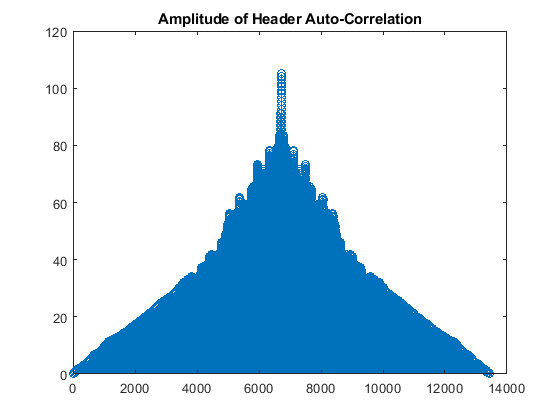

stem(abs(hder_auto_corr))
title('Amplitude of Header Auto-Correlation')

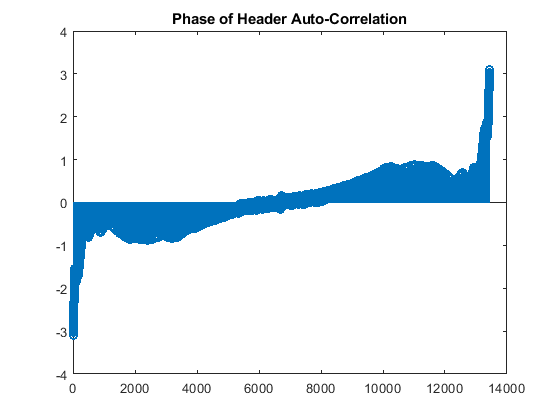

stem(unwrap(angle(hder_auto_corr)))
title('Phase of Header Auto-Correlation')


[~, idx] = max(real(hder_auto_corr))

idx = 6720

angle(hder_auto_corr(idx))*(180/pi)

ans = 0


corr_with_rx_smpl_noise_2_fsk = conv(kernel, rx_smpl_noise_2_fsk)

corr_with_rx_smpl_noise_2_fsk =   -0.0354 - 0.0439i  -0.0274 - 0.0527i   0.0132 - 0.0715i  -0.0395 - 0.0628i  -0.0465 - 0.0798i   0.0170 - 0.0479i   0.0007 - 0.0562i  -0.0087 - 0.0740i   0.0113 - 0.1464i   0.0452 - 0.0999i   0.0878 - 0.0888i   0.0269 - 0.1155i   0.0502 - 0.1406i   0.0319 - 0.1814i   0.0091 - 0.1958i  -0.0140 - 0.2226i   0.0023 - 0.1835i   0.0137 - 0.1535i  -0.0079 - 0.1869i  -0.0158 - 0.2393i  -0.0085 - 0.2279i   0.0290 - 0.2466i   0.0868 - 0.3183i   0.0637 - 0.2946i   0.0368 - 0.3373i   0.0215 - 0.3406i   0.0256 - 0.4124i  -0.0551 - 0.4525i  -0.0571 - 0.4522i  -0.0613 - 0.4469i  -0.1037 - 0.5206i  -0.0628 - 0.5344i  -0.0740 - 0.6088i  -0.0566 - 0.6402i  -0.0660 - 0.6825i   0.0031 - 0.7028i   0.0252 - 0.7335i   0.0519 - 0.7819i   0.0723 - 0.8284i   0.1341 - 0.8368i   0.1663 - 0.8385i   0.2141 - 0.8449i   0.2705 - 0.8393i   0.2890 - 0.8227i   0.3308 - 0.8384i   0.3513 - 0.8040i   0.3303 - 0.7678i   0.3762 - 0.7037i   0.3795 - 0.6654i   0.4121 - 0.6917i


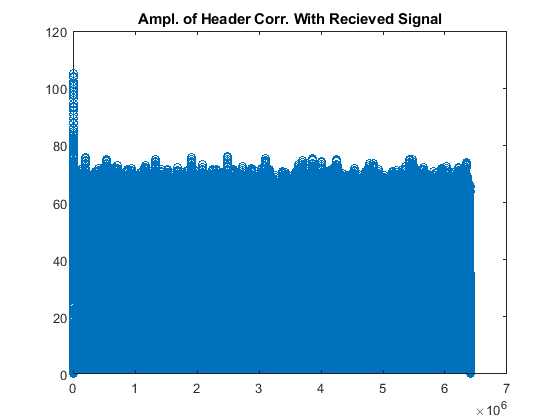

stem(abs(corr_with_rx_smpl_noise_2_fsk))
title('Ampl. of Header Corr. With Recieved Signal')

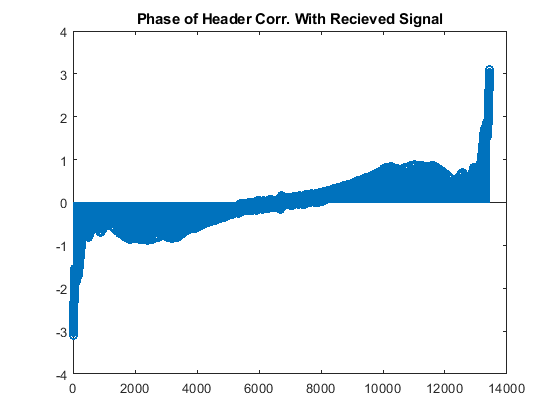

stem(unwrap(angle(hder_auto_corr)))
title('Phase of Header Corr. With Recieved Signal')


[~, idx] = max(real(corr_with_rx_smpl_noise_2_fsk))

idx = 6720

angle(corr_with_rx_smpl_noise_2_fsk(idx))*(180/pi)

ans = 30.8243